# **CVPR 2018, Project 1**

This project is based on the first lab lecture (see the Matlab starter code and images in Moodle). The starter code estimates homographies from a set of checkboard images. 

The goals are:

- calibrating the camera using the Zhang's calibration method

- computing the total reprojection error

- taking into account the radial distortion and compensating it

- comparing the calibration with and without radial distortion compensation

- superimposing an object to the calibration plane

We use both the images in Moodle and other images acquired with my smartphone.

## Zhang's calibration method

Zhang’s calibration method (Zhang, 2000) is an indirect method to calibrate a camera, it first estimates P and then compute the camera parameters (intrinsic ones K and extrinsic ones R and t). It is based on homographies and requires many (at least three) images of a plane . It is easier to get images of a plane instead of an image of a 3D calibration object: it is easier to build a plane with a checkerboard pattern than building a 3D calibration object.

To estimate homographies, we need a set of correspondences (at least four) between 3D points lying on the checkerboard pattern and 2D points in the image. The size of the squares of the pattern is 30mm. A function is available in the Computer Vision Toolbox, for detecting the checkerboard points.

We load the specified group of images, detect the interest points and store the images `I` and the points `XYpixel` in the structure array `imageData`.

%Let the images be located in a subfolder of the current folder called images.
  clear imageData
  mine=true;
  if(mine)
    iimage= 1:22;
    prefix="myImg (";
    suffix=").jpg";
    nrows=6;
    ncols=7;
  else
    iimage=1:20;
    prefix="image";
    suffix=".tif";
    nrows=12;
    ncols=13;
  end
  showDetection=false;
  for ii=1:length(iimage)
      imageFileName = fullfile("images",join([prefix num2str(iimage(ii)) suffix],""));
      
      imageData(ii).I = imread(imageFileName);
   
      imageData(ii).XYpixel = detectCheckerboardPoints(imageData(ii).I);
      imageData(ii).XYpixel_p = detectCheckerboardPoints(imageData(ii).I); % in order to have a copy of the detected points
     
      if(showDetection)
          hnd=figure; %when creating a figure, a handle is returned, that can be used for accessing properties
          imshow(imageData(ii).I)
          hold on
          
          for jj=1:size(imageData(ii).XYpixel,1)
                x=imageData(ii).XYpixel(jj,1);
                y=imageData(ii).XYpixel(jj,2);
                plot(x,y,'or')
                
                hndtxt=text(x,y,num2str(jj));
                set(hndtxt,'fontsize',8,'color','green');
          end
      end
  
  end  


## Establishing correspondences

Given that the square size is 30mm and that all the corner points are detected and the detected points are ordered, we can establish correspondences. For each image we store the coordinates of the points in millimeters along the checkerboard `XYmm` in the structure array `imageData`.

squaresize=30; % [mm]
  
for ii=1:length(iimage)      
    XYpixel=imageData(ii).XYpixel;
    clear Xmm Ymm
    for jj=1:length(XYpixel)
        [row,col]=ind2sub([nrows,ncols],jj); %linear index to row,col 
        
        Xmm=(col-1)*squaresize;
        Ymm=(row-1)*squaresize;
        
        imageData(ii).XYmm(jj,:)=[Xmm Ymm];
    end
end

## Estimating homographies

The field `XYmm` contains the coordinates in millimeters along the checkerboard and the field `XYpixel` the coordinates of the corresponding pixel in the image. Thus, the correspondences have been established.

To estimate the homography we need to estimate the 3x3 matrix $H$ in the following way:


$$w \left[
\begin{array}{c}
u \\ 
v \\ 
1
\end{array} 
\right]=P
\left[
\begin{array}{c}
x \\ 
y \\ 
0 \\
1
\end{array} 
\right]=
\left[
p_1 \; p_2 \; p_3 \; p_4
\right]
\left[
\begin{array}{c}
x \\ 
y \\ 
0 \\
1
\end{array} 
\right]=
\underbrace{\left[
p_1 \; p_2 \;  p_4
\right]}_{\doteq H}
\underbrace{\left[
\begin{array}{c}
x \\ 
y \\ 
1
\end{array} 
\right]}_{\doteq m}$$


where $u,v$ are the pixel coordinates and $x,y$ the mm coordinates. 

By partitioning $H$row-wise as


$$H=\left[
\begin{array}{c}
h_1^\top \\ 
h_2^\top \\ 
h_3^\top
\end{array} 
\right]$$


we obtain two homogeneous equations for each correspondence:

$\left[
\begin{array}{ccc}
m^\top & 0^\top & -um^\top \\ 
0^\top & m^\top & -vm^\top 
\end{array} 
\right]
\left[
\begin{array}{c}
h_1 \\ 
h_2 \\ 
h_3
\end{array} 
\right]=0$.

We need to stack the equations and get a homogeneous linear system of equations such as:


$$Ax=0$$


that we can solve in the least squares sense under the constraint that

$x \neq 0$.

The solution is the right singular value of $A=U\Sigma V^\top$ associated with the smallest singular value, i.e. the rightmost column of $V$.

  


for ii=1:length(iimage)
  XYpixel=imageData(ii).XYpixel_p;
  XYmm=imageData(ii).XYmm;
  
  imageData(ii).H=getHomography(XYmm,XYpixel);
end
  
  

## Computing intrinsic parameters

Given the estimated homography ***H*** of the 3D plane ***Π*** to the image plane:


$$H=\lambda \left\lbrack p_{1\;} {\;p}_{2\;} \;p_4 \right\rbrack$$


Since $P=K\left\lbrack R\;|\;t\right\rbrack =K\left\lbrack r_{1\;} r_2 \;r_3 \;t\right\rbrack$ we get $p_1 ={\mathrm{Kr}}_1$, $p_2 ={\textrm{Kr}}_2$, $p_4 =\mathrm{Kt}$ and by substitution: $H=\lambda K\left\lbrack r_{1\;} r_2 \;\;t\right\rbrack$.

Thus (9):

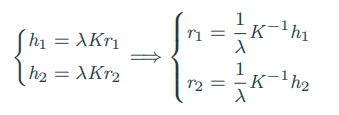 

Now, being ***R*** a rotation matrix, we have

Thus, from a plane ***Π*** and the corresponding estimated homography ***H*** we get two scalar constraints:

where $B=\left({\mathrm{KK}}^T {\left.\right)}^{-1} \right.$ . The constraints are linear in the unknown ***B***.

By taking *n* planes and the corresponding estimated homographies ***Π (k) , H (k) k = 1, . . . , n*** we get *2n* constraints on the same **B**.

Note that $B=B^T$ by construction, so ***B*** is symmetric; hence there are 6 unknowns.

Let $b=\left\lbrack B_{11} \;B_{\mathrm{12}} \;B_{\mathrm{22}} \;B_{\mathrm{13}} \;B_{\mathrm{23}} \;B_{\mathrm{33}} {\left.\right\rbrack }^T \right.$ be the vector of the unknowns. 

For*** i, j ***∈ {1, 2}, it’s easily verified that $h_i^T {\mathrm{Bh}}_j =v_{\mathrm{ij}}^T b$ where

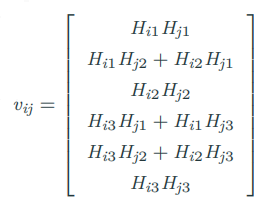

Thus, the two equations become

For *n* planes, by stacking equations of the above form, we get ***Vb = 0 ***where ***V*** is *2n × 6*.

We can solve the linear system of equations in the least squares sense under the constraint that $b \neq 0$.

The solution is the right singular value of $V=U\Sigma S^\top$ associated with the smallest singular value, i.e. the rightmost column of $S$.

Given $B=\left({\mathrm{KK}}^T {\left.\right)}^{-1} \right.$ , the matrix ***K*** can be found by the Cholesky factorization. Recall that any real symmetric and positive definite matrix can be decomposed uniquely as the product of lower triangular matrix having strictly positive eigenvalues and its transpose (Cholesky factorization). Let $B={\mathrm{LL}}^T$ be the Cholesky factorization of ***B***, where ***L*** is lower triangular. On the other hand we have $B=\left({\mathrm{KK}}^T {\left.\right)}^{-1} =\left(K^T {\left.\right)}^{-1} K^{-1} =\left(K^{-1} {\left.\right)}^T K^{-1} \right.\right.\right.$ where $\left(K^{-1} {\left.\right)}^T \right.$ is lower triangular, being the transpose of an upper triangular matrix. By comparison, we get $K^{-1} =L^T \;\;\Rightarrow \;\;K=\left(L^T {\left.\right)}^{-1} \right.$ . As usual, the proper scale for *K* is obtained by imposing $K_{33} =1$.

K0 = getK(imageData);


## Computing extrinsic parameters

The extrinsic parameters for each image can be computed from $H=\lambda K\left\lbrack r_{1\;} r_2 \;\;t\right\rbrack$.

where $\lambda =1/||K^{-1} h_1 ||=1/||K^{-1} h_2 ||$ and × denotes cross product. Due to noise, the resulting matrix ***R*** may not be orthogonal. The closest (in the Frobenius norm) orthogonal matrix ***R′*** to a given matrix ***R*** is known to be (see for instance (Golub and Van Loan, 1996), pg. 601) $R\prime ={\mathrm{UV}}^T$ where $R=U\Sigma V^T$ is the singular value decomposition of ***R***.

 For each image store the extrinsic parameters ***R*** and ***t*** in the structure array `imageData`. Compute and store also the perspective projection matrix $P=K\left\lbrack R\;\;t\right\rbrack$.

for ii=1:length(iimage)
  H=imageData(ii).H;
  [R t]= getRt(K0,H);
  imageData(ii).R=R;
  imageData(ii).t=t;
  P= K0*[imageData(ii).R imageData(ii).t];    
  %normalize P
  P = P/norm(P(3,1:3));
  imageData(ii).P0=P;% in order to have a copy of the original P
  imageData(ii).P=P;
end





## Computing the total reprojection error

The total reprojection error is the distance between the estimated and the measured projections:

The estimated projections are computed using the perpective projection matrix ***P*** and ***m *** where ***m ***is build with the first two coordinates from `XYmm, `the third coordinate is 0 and the last 1. The measured projections are stored in `XYpixel`.

We compute the total reprojection error for an image and plot estimated (red) and measured projections (green).

ii=3;
P=imageData(ii).P0;
XYpixel=imageData(ii).XYpixel;
XYmm=imageData(ii).XYmm;
err=0;
imshow(imageData(ii).I)
hold on
for jj=1:length(XYmm)
    homogeneous = [XYmm(jj,1);XYmm(jj,2);0;1];
    proj_hom=P*homogeneous;
      
    proj=[ proj_hom(1,1)./proj_hom(3,1);...
          proj_hom(2,1)./proj_hom(3,1)];
    
    err=err+(XYpixel(jj,1)-proj(1))^2+(XYpixel(jj,2)-proj(2))^2;
    
    p=plot(proj(1,1),proj(2,1),'rs');
    p=plot(XYpixel(jj,1),XYpixel(jj,2),'gs');
          
end
imageData(ii).err=err;
err


## Estimating radial distortion parameters

For more accurate camera modeling, radial distortion has to be taken into account. Radial distortion appears at the periphery of the image, especially for short focal length.

A simple model for radial distortion has two parameters, $k_1$ and $k_2$ (5):

where ***u***, ***v*** are the ideal projections (in absence of radial distortion), $\hat{u}$, $\hat{v}$ are the actual projections (that are stored in `XYpixel`) and

 

Equations (5) may be rewritten as

Given ***P***, the ideal (undistorted) coordinates*** (u, v)*** can be computed from the 3D coordinates ***(x, y, z)***, where*** z*** is 0 and ***x*** and ***y*** are stored in `XYmm`, by applying the projection.

Thus we obtain a linear system (6) of two equations in the unknowns $k_1$ and $k_2$. Notice that $r_d$ is also known because from ***K*** we get $u_0$, $v_0$, $\alpha_u$, $\alpha_v$. In practice it is advisable to use many correspondences and solve the resulting overdetermined system

using the least squares:

k0=estimate_k1k2(imageData);% in order to have a copy of the origina k1 and k2
k=estimate_k1k2(imageData);

## Calibrating with radial distortion compensation

In order to calibrate the camera compensating radial distortion many iterations are made, for each iteration we perform the following steps:

- estimating homographies, intrinsic parameters and extrinsic parameters using the given correspondences (`XYmm` and `XYpixel_p`)

- computing the Frobenius norm of the difference between the perspective projection matrix of the current iteration and the one of the previous iteration

- estimating radial distortion parameters $k_1$and $k_2$

- computing the Euclidean norm of the difference between the vector$\left(k_1 \;,k_2 \right)$ of the current iteration and the one of the previous iteration

- compensating for radial distortion and get new projections and so correspondences (`XYmm` and `XYpixel_p`)

Once $k_1$and $k_2$ have been estimated, the radial distortion can be compensated by inverting the transformation. If we switch to normalized coordinates

equations (5) may be rewritten as

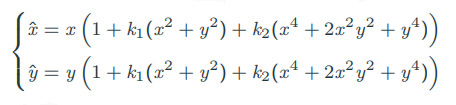

Thus, the ideal (undistorted) coordinates ***x, y*** may be obtained from the actual (distorted, that are in `XYpixel`) by solving a non-linear system of equations in the unknowns*** x, y***, for example using the function `fsolve. `Then from ***x, y ***we obtain the new projections and so the new correspondences for all the systems that have been solved successfully, saving them into `XYmm` and `XYpixel_p `replacing the previous ones`.`

The loop finishes because there is a maximum number of iteration` maxRep, `or because both the persepective projection matrices ***P*** (there is a matrix ***P ***for each image) and the radial distortion parameters  ***k ***have reach the state of convergence (the matrices ***P ***and the vector ***k ***are distant less than a given tolerance, `tolP` and `tolk1k2`, from the ones of the previous iteration with respect to Frobenius and Euclidean norm respectively). Another stop criterion can be to check the convergence of the total reprojection error.

% iterate for a max number of iterations
% stop iterating if the matrix P and k1 and k2 are not changing so much
maxRep=100;
tolP=10^-2;
tolk1k2=10^-4;
ll=0;
stopP=false;
stopk1k2=false;
while ll<maxRep && not(stopP && stopk1k2) 
    ll=ll+1;
    % compute homographies
    for ii=1:length(iimage)
      XYpixel=imageData(ii).XYpixel_p;
      XYmm=imageData(ii).XYmm;
      imageData(ii).H=getHomography(XYmm,XYpixel);
    end
    % compute intrinsic parameters
    K = getK(imageData);
    % compute extrinsic parameters
    for ii=1:length(iimage)
      H=imageData(ii).H;
      [R t]= getRt(K,H);
      imageData(ii).R=R;
      imageData(ii).t=t;
      P= K*[imageData(ii).R imageData(ii).t];    
      %normalize P
      P = P/norm(P(3,1:3));
      dP=norm(P-imageData(ii).P,'fro');
      imageData(ii).dP=dP;
      imageData(ii).P=P;
    end
    allTol=true;
    for ii=1:length(iimage)
        allTol = allTol && imageData(ii).dP<tolP; % P is not changing so much
    end
    stopP = stopP || (ll>1 && allTol); % for all the images P is not changing so much and at least one iteration has been made
    % compute radial distortion parameters
    kk=estimate_k1k2(imageData);
    dk=norm(k-kk);
    if(ll>1 && dk<tolk1k2) % k1k2 are not changing so much and at least one iteration has been made
      stopk1k2=true;
    end
    k=kk;
    % compensate radial distortion
    for ii=1:length(iimage)
        [outXYmm outXYpixel] = compensateR(imageData(ii),K,k);
        imageData(ii).XYmm=outXYmm;
        imageData(ii).XYpixel_p=outXYpixel;
    end
end
%disp([ll stopP stopk1k2])

## Comparing the calibration with and without radial distortion compensation

We compute the total error projection considering the calibration with and without the radial distortion, we do this for all the images saving the values in `err` and `errComp` respectively.

We plot the images with estimated without radial distortion (red), estimated with radial distortion (blue) and measured projections (green).

We can notice that the total reprojection error for the projections estimated using the calibration with the radial distortion compensation is less than the one using the calibraion without the radial distortion compensation.

for ii=1:length(imageData)
    P0= imageData(ii).P0;
    P= imageData(ii).P;
    
    XYpixel=imageData(ii).XYpixel;
    XYmm=imageData(ii).XYmm;
   
    figure
    imshow(imageData(ii).I)
    hold on
    err=0;
    errComp=0;
    for jj=1:length(XYmm)
        homogeneous = [XYmm(jj,1);XYmm(jj,2);0;1];
        proj_hom=P0*homogeneous;
                  
        proj=[ proj_hom(1,1)./proj_hom(3,1);...
              proj_hom(2,1)./proj_hom(3,1)];
                  
        err=err+(XYpixel(jj,1)-proj(1))^2+(XYpixel(jj,2)-proj(2))^2;
        p=plot(proj(1,1),proj(2,1),'rs');
        
        proj_hom=P*homogeneous;
                  
        proj=[ proj_hom(1,1)./proj_hom(3,1);...
              proj_hom(2,1)./proj_hom(3,1)];
                  
        proj=compensate(K,k,proj);
        errComp=errComp+(XYpixel(jj,1)-proj(1))^2+(XYpixel(jj,2)-proj(2))^2;
          
        p=plot(proj(1,1),proj(2,1),'bs');
        p=plot(XYpixel(jj,1),XYpixel(jj,2),'gs');
    end
    imageData(ii).err=err;
    err
    imageData(ii).errComp=errComp;
    errComp
end

We can visualize a barplot comparing the calibration with and without radial distortion.

errs=[];
for ii=1:length(imageData)
    errs(ii,1)=imageData(ii).err;
    errs(ii,2)=imageData(ii).errComp;
end
figure
bar(errs)


## Superimposing an object to the calibration plane

We superimpose a kind of tiered empty cake to each image: we compute the coordinates of the lateral surface and the top surface of many cylinders (`nmax`) one over the other with decreasing radius. We do not compute all the lateral surface and top surface in order to see inside the empty object.

colors=['cs';'rs';'gs';'ys';'ms'];
for ii=1:length(imageData)
    figure
    imshow(imageData(ii).I)
    hold on
    
    vtheta=0:0.01:1.5*pi;
    centerX=150;
    centerY=90;
    nmax=5; % how many cylinders
    sh=90/nmax;
    rh=60/nmax;
    for kk=1:nmax
        radius=(nmax-kk+1)*rh;
        vX=centerX+radius*cos(vtheta);
        vY=centerY+radius*sin(vtheta);
        vZs= -(kk*sh:1:(kk+1)*sh);
        
        P= imageData(ii).P;
        
        ones_v=ones(1,length(vtheta));    
        color=colors(1+mod(kk,length(colors)));
        for z=1:length(vZs)
            vZ=vZs(z);
            homogeneous = [vX; vY; vZ*ones_v; ones_v];
            proj_hom=P*homogeneous;
              
            proj=[ proj_hom(1,:)./proj_hom(3,:);...
                  proj_hom(2,:)./proj_hom(3,:)];
            
            projC=compensate(K,k,proj);      
            
            plot(proj(1,:),proj(2,:),color);
        end
        % top surface
        for r=(nmax-kk)*rh:1:radius
          vX=centerX+r*cos(vtheta);
          vY=centerY+r*sin(vtheta);
          homogeneous = [vX; vY; vZs(end)*ones_v; ones_v];
          proj_hom=P*homogeneous;
          
          proj=[ proj_hom(1,:)./proj_hom(3,:);...
              proj_hom(2,:)./proj_hom(3,:)];
          
          projC=compensate(K,k,proj);
          p=plot(proj(1,:),proj(2,:),'bs');
        end
    end
end 

function H = getHomography(XYmm,XYpixel)
%get homography
  A=[];
  b=[];
  for jj=1:length(XYpixel)
      Xpixel=XYpixel(jj,1);
      Ypixel=XYpixel(jj,2);
      Xmm=XYmm(jj,1);
      Ymm=XYmm(jj,2);
     
      m=[Xmm; Ymm; 1];
      O=[0;0;0];
      A=[A; m' O' -Xpixel*m';O' m' -Ypixel*m']; %#ok
      b=[b;0;0]; %#ok       
  end
  [U,S,V]=svd(A);
  h=V(:,end); % the right  singular vector associated to the smallest singular value
  H=reshape(h,[3 3])'; %reshape acts column-wise so we neet to transpose
  % check determinant of H, if negative then change sign
  if(det(H)<0)
      H=-H;
  end
end

function K = getK(imageData)
%compute intrinsic parameters given a cell array of homographies
    V = [];
    for ii=1:length(imageData)
      H=imageData(ii).H;
      v=[
          (get_v_ij(H,1,2))';
          (get_v_ij(H,1,1)-get_v_ij(H,2,2))'
      ];
      V=[V;v];
    end
    
    [U,S,W]=svd(V);
    b=W(:,end); % the right  singular vector associated to the smallest singular value
    
    B = zeros(3);
    % put values into upper part
    B(triu(ones(3),0)==1) = b;
    % get symmetric matrix
    B = (B+B') - eye(size(B,1)).*diag(B);
    
    % check if B is positive definite, if not changhe the sign
    if(not(all(eig(B)>0)))
        B=-B;
    end
    
    % compute cholesky factorization of B=LL'=(KK')^(-1)
    % B=K'^(-1)K^(-1)=(K^(-1))'K^(-1)
    % L'=K^(-1) so K= L'^(-1)
    K = inv(chol(B,'lower')');
    
    %normalize K
    
    K = K/K(3,3);
end

function v=get_v_ij(H,i,j)
% utility function to get intermediate vector v_ij from Homography matrix
    v=[
        H(1,i)*H(1,j);
        H(1,i)*H(2,j)+H(2,i)*H(1,j);
        H(2,i)*H(2,j);
        H(3,i)*H(1,j)+H(1,i)*H(3,j);
        H(3,i)*H(2,j)+H(2,i)*H(3,j);
        H(3,i)*H(3,j);
    ];
end

function [R t] = getRt(K,H)
  k_h1=K\H(:,1);
  lambda=1/norm(k_h1);
  R=[
      lambda*k_h1, lambda*(K\H(:,2))
  ];
  R=[R cross(R(:,1),R(:,2))];
  [U,S,V] = svd(R);
  R=U*V';
  t=lambda*(K\H(:,3));
end

function k = estimate_k1k2(imageData)
    K=getK(imageData);
    b=[];
    A=[];
    for ii=1:length(imageData)
        P= K*[imageData(ii).R imageData(ii).t];
              
        %normalize P
        P = P/norm(P(3,1:3));
        
        XYpixel=imageData(ii).XYpixel_p;
        XYmm=imageData(ii).XYmm;
        u0=K(1,3);
        v0=K(2,3);
        au=K(1,1);
        av=K(2,2);
        for jj=1:length(XYmm)
              homogeneous = [XYmm(jj,1);XYmm(jj,2);0;1];
              proj_hom=P*homogeneous;
                  
              proj=[ proj_hom(1,1)./proj_hom(3,1);...
                      proj_hom(2,1)./proj_hom(3,1)];
               
              u=proj(1);
              v=proj(2);
              du=XYpixel(jj,1)-u;
              dv=XYpixel(jj,2)-v;
              u_u0=u-u0;
              v_v0=v-v0;
              rd2=(u_u0/au)^2+(v_v0/av)^2;
              
              b=[b;du;dv];
              A=[A;u_u0*rd2 u_u0*rd2^2;v_v0*rd2 v_v0*rd2^2];
                  
        end
    end
    k=inv(A'*A)*A'*b;
end

%compensate radial distortion
function projC = compensate(K,k,proj)
    u=proj(1);
    v=proj(2);
    
    u0=K(1,3);
    v0=K(2,3);
    au=K(1,1);
    av=K(2,2);
    u_u0=u-u0;
    v_v0=v-v0;
    x=u_u0/au;
    y=v_v0/av;
    rd2=(u_u0/au)^2+(v_v0/av)^2;
     
    %compensate
    ud=u_u0*rd2*k(1)+ u_u0*rd2^2*k(2)+u;
    vd=v_v0*rd2*k(1)+ v_v0*rd2^2*k(2)+v;
    
    projC=[ud;vd];
          
end

function fun = getFun(xh,k)
    fun= @(x) ( [ 
        -xh(1)+x(1)*(1+k(1)*(x(1)^2+x(2)^2)+k(2)*(x(1)^4+2*x(1)^2*x(2)^2+x(2)^4)); 
        -xh(2)+x(2)*(1+k(1)*(x(1)^2+x(2)^2)+k(2)*(x(1)^4+2*x(1)^2*x(2)^2+x(2)^4))  
        ]);
end

function [outXYmm outXYpixel] = compensateR(imageData,K,k)
    XYmm=imageData.XYmm;
    XYpixel=imageData.XYpixel;
    P= K*[imageData.R imageData.t];
    %normalize P
    P = P/norm(P(3,1:3));
    u0=K(1,3);
    v0=K(2,3);
    au=K(1,1);
    av=K(2,2);
    outXYmm=[];
    outXYpixel=[];
    options = optimset('Display','off');
    ns=0;
    for jj=1:length(XYmm)
        homogeneous = [XYmm(jj,1);XYmm(jj,2);0;1];
        proj_hom=P*homogeneous;      
        u = proj_hom(1,1)./proj_hom(3,1);
        v = proj_hom(2,1)./proj_hom(3,1);
        x=(u-u0)/au;
        y=(v-v0)/av;
        x0=[x;y];
        dx=(XYpixel(jj,1)-u0)/au;
        dy=(XYpixel(jj,2)-v0)/av;
        xh=[dx;dy];
        %Solve non linear system
        fun = getFun(xh,k); 
        [x, val, exitflag] = fsolve(fun,xh,options);
        if(exitflag>=0) % equation solved
            projj=[x(1)*au+u0 x(2)*av+v0];
            outXYmm=[outXYmm; XYmm(jj,:)];
            outXYpixel=[outXYpixel; projj];
        else
            ns=ns+1;
        end
    end
    if(ns>0)
        disp("solutions not found")
        ns
    end
end